# compareBB

Script to load previously saved splWindow .mat files and compare broadband metrics

clearvars

tog.VOI = 'OcEnd-19';
tog.saveIt = 'no';

par.fontSize = 14;                          %font size for plots
par.lineWidth = 4;                          %width of means polarplot line
par.smooth = 120;                            %number of windows to use for smoothing means


% C:\Users\510PAS\PhD\Data\NW_2019\' tog.VOI '.mat'

cd C:\Users\510PAS\PhD\Data\NW_2019\OcEnd
files = dir('*.mat');
if length(files) == 4
    col=['g' 'b' 'g' 'b'];
    shape=['--' '--' '-.' '-.'];
elseif length(files) == 6
    col=['g' 'b' 'r' 'g' 'b' 'r'];
    shape=['--' '--' '--' '-.' '-.' '-.'];
elseif length(files) == 8
    col=['g' 'b' 'r' 'm' 'g' 'b' 'r' 'm'];
    shape=['--' '--' '--' '--' '-.' '-.' '-.' '-.'];
elseif length(files) == 10
    col=['g' 'b' 'r' 'm' 'c' 'g' 'b' 'r' 'm' 'c'];
    shape=['--' '--' '--' '--' '--' '-.' '-.' '-.' '-.' '-.'];
end
lobData = cell(size(files));
for ii=1:length(files)
    aFileData = load(files(ii).name);
    lobData{ii} = aFileData; %.data;
end

minSpd = min(cell2mat(cellfun(@(x) min(x.SPL.sog), lobData, 'UniformOutput', false)));
maxSpd = max(cell2mat(cellfun(@(x) max(x.SPL.sog), lobData, 'UniformOutput', false)));

minBB = min(cell2mat(cellfun(@(x) min(x.BB(1,:)), lobData, 'UniformOutput', false)));
maxBB = max(cell2mat(cellfun(@(x) max(x.BB(1,:)), lobData, 'UniformOutput', false)));

par.bbLim = [minBB-10 maxBB];                      %range for broadband polar plot
par.nbLim = [120 165];                      %range for narrowband polar plot

### Broadband

%p = gobjects(length(lobData)+1,4);
h = figure('units','normalized','outerposition',[0 0 0.8 0.8])

h =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0024 0.0038 0.7952 0.7676]
       Units: 'normalized'

  Show all properties


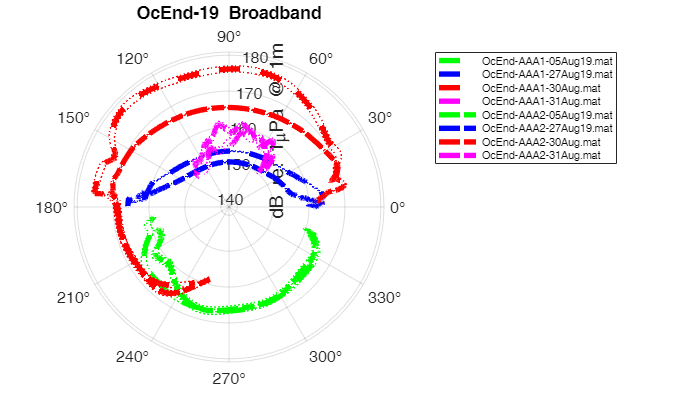

for i=1:length(files)
    rads = lobData{i,1}.SPL.rads(:,24)';
    levels = smoothdata(mean(lobData{i,1}.BB,1),'gaussian',par.smooth);
    stddev = smoothdata(std(lobData{i,1}.BB,0,1),'gaussian',par.smooth);
    polarplot(rads,levels,'LineStyle',shape(2*i-1:2*i),'LineWidth',par.lineWidth,'Color',col(i),'DisplayName',files(i).name);
    hold on
    polarplot(rads,levels+stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col(i),'HandleVisibility','off');
    polarplot(rads,levels-stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col(i),'HandleVisibility','off');
end
rlim(par.bbLim)
title([tog.VOI '  Broadband'])
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize-2;
legend('FontSize',8,'Location','northeastoutside')
saveas(gcf, fullfile([tog.VOI '-bbMerge.tif']))

Tonal 1 **Need to update this for tonal(i)

h = figure('units','normalized','outerposition',[0 0 0.8 0.8])

h =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 0.8000 0.8000]
       Units: 'normalized'

  Show all properties


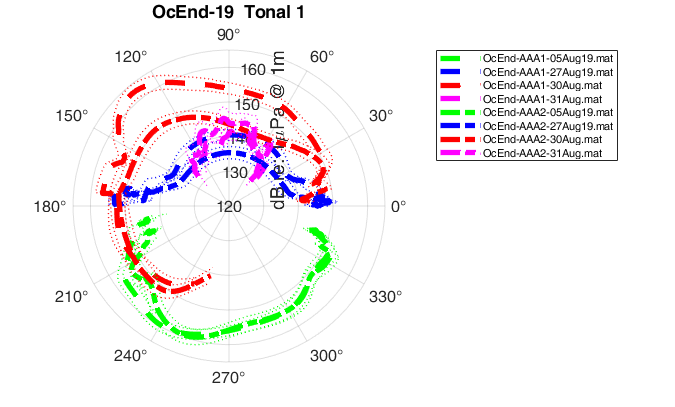

for i=1:length(files)
    rads = lobData{i,1}.SPL.rads(:,24)';
    levels = smoothdata(mean(lobData{i,1}.tonal1.max',1),'gaussian',par.smooth);
    stddev = smoothdata(std(lobData{i,1}.tonal1.max',0,1),'gaussian',par.smooth);
    polarplot(rads,levels,'LineStyle',shape(2*i-1:2*i),'LineWidth',par.lineWidth,'Color',col(i),'DisplayName',files(i).name);
    hold on
    polarplot(rads,levels+stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col(i),'HandleVisibility','off');
    polarplot(rads,levels-stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col(i),'HandleVisibility','off');
end
rlim(par.nbLim)
title([tog.VOI '  Tonal 1'])
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize-2;
legend('FontSize',8,'Location','northeastoutside')
% switch 'tog.saveIt'
%     case 'no'
%     case 'yes'
saveas(h, fullfile([tog.VOI '-Tonal1.tif']));

% end


Tonal 2

h = figure('units','normalized','outerposition',[0 0 0.8 0.8])

h =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 0.8000 0.8000]
       Units: 'normalized'

  Show all properties


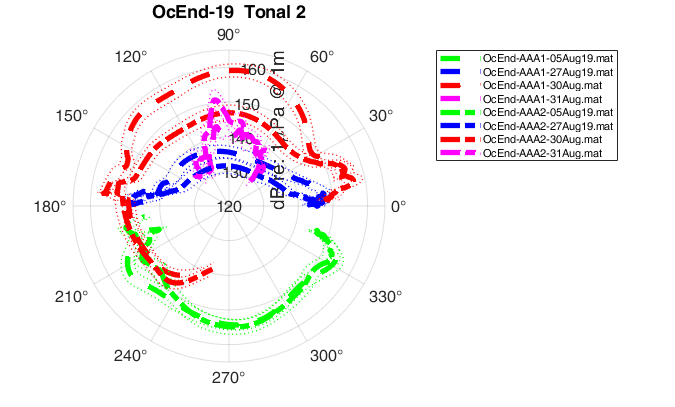

for i=1:length(files)
    rads = lobData{i,1}.SPL.rads(:,24)';
    levels = smoothdata(mean(lobData{i,1}.tonal2.max',1),'gaussian',par.smooth);
    stddev = smoothdata(std(lobData{i,1}.tonal2.max',0,1),'gaussian',par.smooth);
    polarplot(rads,levels,'LineStyle',shape(2*i-1:2*i),'LineWidth',par.lineWidth,'Color',col(i),'DisplayName',files(i).name);
    hold on
    polarplot(rads,levels+stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col(i),'HandleVisibility','off');
    polarplot(rads,levels-stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col(i),'HandleVisibility','off');
end
rlim(par.nbLim)
title([tog.VOI '  Tonal 2'])
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize-2;
legend('FontSize',8,'Location','northeastoutside')
% switch 'tog.saveIt'
%     case 'no'
%     case 'yes'
saveas(h, fullfile([tog.VOI '-Tonal2.tif']));

% end


Tonal 3

h = figure('units','normalized','outerposition',[0 0 0.8 0.8])

h =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 0.8000 0.8000]
       Units: 'normalized'

  Show all properties


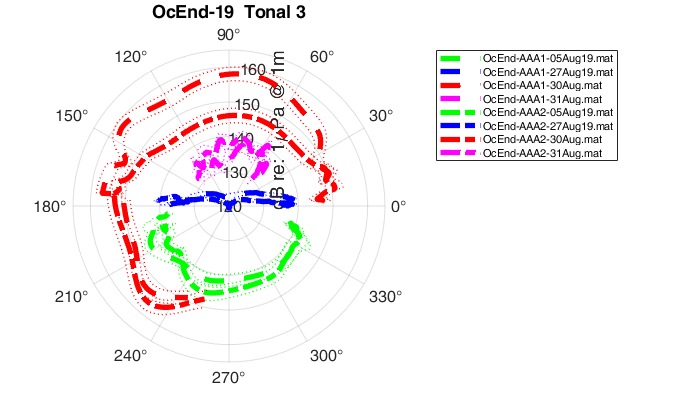

for i=1:length(files)
    rads = lobData{i,1}.SPL.rads(:,24)';
    levels = smoothdata(mean(lobData{i,1}.tonal3.max',1),'gaussian',par.smooth);
    stddev = smoothdata(std(lobData{i,1}.tonal3.max',0,1),'gaussian',par.smooth);
    polarplot(rads,levels,'LineStyle',shape(2*i-1:2*i),'LineWidth',par.lineWidth,'Color',col(i),'DisplayName',files(i).name);
    hold on
    polarplot(rads,levels+stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col(i),'HandleVisibility','off');
    polarplot(rads,levels-stddev,'LineWidth',par.lineWidth/4,'LineStyle',':','Color',col(i),'HandleVisibility','off');
end
rlim(par.nbLim)
title([tog.VOI '  Tonal 3'])
ax = gca;
rruler = ax.RAxis;
rruler.Label.String = 'dB re: 1\muPa @ 1m';
ax.FontSize = par.fontSize-2;
legend('FontSize',8,'Location','northeastoutside')
% switch 'tog.saveIt'
%     case 'no'
%     case 'yes'
saveas(h, fullfile([tog.VOI '-Tonal3.tif']))

% end


Speed correlation for broadband

h = figure('units','normalized','outerposition',[0 0 0.8 0.8]);
sz = 20;
for i=1:length(files)
    speed = lobData{i,1}.SPL.sog';
    levels = lobData{i,1}.BB;
    scatter(speed,levels(1,:),sz,col(i),'filled','DisplayName',files(i).name);
    hold on
    p=polyfit(speed,levels(1,:),1);
    x1 = [minSpd maxSpd];
    y1 = polyval(p,x1);
    plot(x1,y1,'Color',col(i),'LineStyle',shape(2*i-1:2*i),'HandleVisibility','off')
end
title('Speed vs Broadband RNL')
ylabel('dB re: 1\muPa @ 1m')
xlabel('kts')
xlim([minSpd maxSpd])
ylim([minBB maxBB])
% lsFit = lsline;
% for i=1:length(files)
%     lsFit(i).Color=col(i);
%     lsFit(i).HandleVisibility = 'off';
%     lsFit(i).LineStyle = shape(2*i-1:2*i);
% end
lgd = legend

lgd =   Legend (OcEnd-AAA1-05Aug19.mat, OcEnd-AAA1-27Aug19.mat, OcEnd-AAA1-30Aug.mat, OcEnd-AAA1-31Aug.mat, OcEnd-AAA2-05Aug19.mat, OcEnd-AAA2-27Aug19.mat, OcEnd-AAA2-30Aug.mat, OcEnd-AAA2-31Aug.mat) with properties:

         String: {'OcEnd-AAA1-05Aug19.mat'  'OcEnd-AAA1-27Aug19.mat'  'OcEnd-AAA1-30Aug.mat'  'OcEnd-AAA1-31Aug.mat'  'OcEnd-AAA2-05Aug19.mat'  'OcEnd-AAA2-27Aug19.mat'  'OcEnd-AAA2-30Aug.mat'  'OcEnd-AAA2-31Aug.mat'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7495 0.7605 0.1473 0.1518]
          Units: 'normalized'

  Show all properties


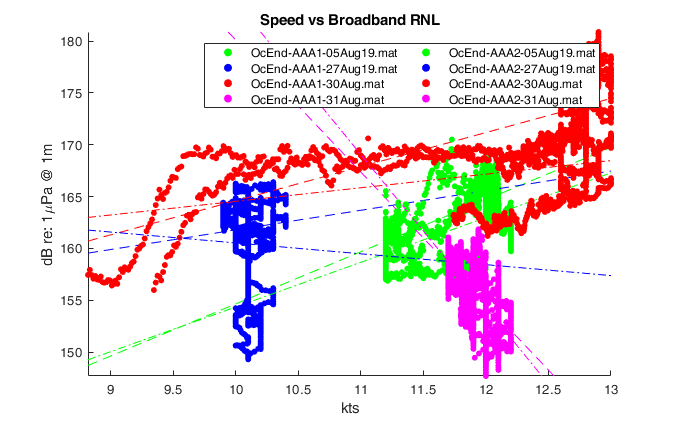

lgd.NumColumns = 2;

saveas(h, fullfile([tog.VOI '-SpdvsBB']))

Speed correlation for tonal 1

h = figure('units','normalized','outerposition',[0 0 0.8 0.8])

h =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 0.8000 0.8000]
       Units: 'normalized'

  Show all properties


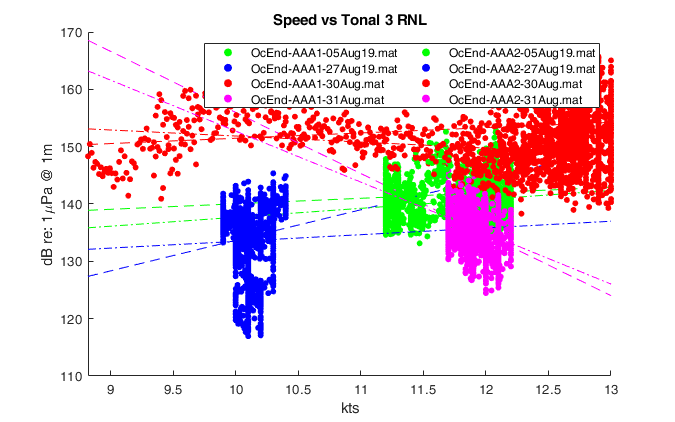

sz = 20;
for i=1:length(files)
    speed = lobData{i,1}.SPL.sog';
    levels = lobData{i,1}.tonal3.max';
    s(i)=scatter(speed,levels(1,:),sz,col(i),'filled','DisplayName',files(i).name);
    hold on
    p=polyfit(speed,levels(1,:),1);
    x1 = [minSpd maxSpd];
    y1 = polyval(p,x1);
    plot(x1,y1,'Color',col(i),'LineStyle',shape(2*i-1:2*i),'HandleVisibility','off')

end
title('Speed vs Tonal 3 RNL')
ylabel('dB re: 1\muPa @ 1m')
xlabel('kts')
xlim([minSpd maxSpd])
%ylim([minBB maxBB])
lgd = legend;
lgd.NumColumns = 2;

saveas(h, fullfile([tog.VOI 'SpdvsTonal']))